# Homework 2 - Computational Problems

## Problem 1

type ball_intrp.m


function [time_imp, range_imp] = ball_intrp(airFlag, tau)
% find range and time for a ball.
% inputs:
%   airFlag: 0 or 1 to determine air resistance in problem
%   tau: time step

%* Set initial position and velocity of the baseball
y1 = 0;
r1 = [0, y1];     % Initial vector position
speed = 50; % m/s
theta = 45; % deg
v1 = [speed*cos(theta*pi/180), ...
      speed*sin(theta*pi/180)];     % Initial velocity
r = r1;  v = v1;  % Set initial position and velocity

%* Set physical parameters (mass, Cd, etc.)
Cd = 0.35;      % Drag coefficient (dimensionless)
area = 4.3e-3;  % Cross-sectional area of projectile (m^2)
grav = 9.81;    % Gravitational acceleration (m/s^2)
mass = 0.145;   % Mass of projectile (kg)
if( airFlag == 0 )
  rho = 0;      % No air resistance
else
  rho = 1.2;    % Density of air (kg/m^3)
end
air_const = -0.5*Cd*rho*area/mass;  % Air resistance constant

%* Loop until ball hits ground or max steps completed
maxstep = 1000;   % Maximum number of steps
for istep=1:maxs


tau = [0.5, 0.1, 0.01]; % time step in sec
% calculate results
range = zeros(length(tau));
time = range;
disp("tau time range")

tau time range


for i = 1:length(tau)
    [time(i), range(i)] = ball_intrp(0, tau(i));
    fprintf("%f %f %f\n", tau(i), time(i), range(i))
end

0.500000 3.871087 3.629144
0.100000 1.259956 1.242930
0.010000 0.027459 0.027421


## Problem 3

get different data points

type ball_coef.m


function [xplot, yplot, dx, dt] = ball_coef(table, airFlag, tau)
% find trajectory for a ball.
% inputs:
%   airFlag: 0 or 1 to determine air resistance in problem
%   tau: time step

%* Set initial position and velocity of the baseball
y1 = 0;
r1 = [0, y1];     % Initial vector position
speed = 50; % m/s
theta = 45; % deg
v1 = [speed*cos(theta*pi/180), ...
      speed*sin(theta*pi/180)];     % Initial velocity
r = r1;  v = v1;  % Set initial position and velocity

%* Set physical parameters (mass, Cd, etc.)
Cd = 0.35;      % Drag coefficient (dimensionless)
area = 4.3e-3;  % Cross-sectional area of projectile (m^2)
grav = 9.81;    % Gravitational acceleration (m/s^2)
mass = 0.145;   % Mass of projectile (kg)
if( airFlag == 0 )
  rho = 0;      % No air resistance
else
  rho = 1.2;    % Density of air (kg/m^3)
end

air_const = -0.5*Cd*rho*area/mass;  % Air resistance constant

%* Loop until ball hits ground or max steps completed
maxstep = 1000;   % Maximum number of steps
for istep=1:

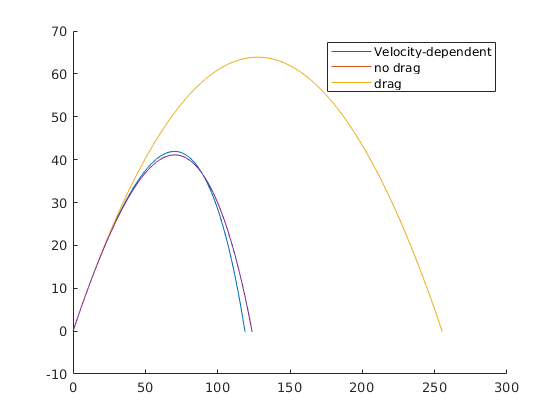


[x, y, dx, dt] = ball_coef(1, 1, 0.01);
[xb, yb] = ball(1, 0.01);
[x_noair, y_noair] = ball(0, 0.01);
[x2, y2, dx_fix, dt_fix] = ball_coef(0, 1, 0.01);
% plot results
hold on
plot(x, y)
plot(xb, yb)
plot(x_noair, y_noair)
plot(x2, y2)
hold off
legend('Velocity-dependent', 'no drag', 'drag')

% range and time of flight for fixed vs dependent
disp("range and time of flight for velocity dependent drag force")

range and time of flight for velocity dependent drag force


fprintf("%f %f \n", dx, dt)

118.818538 5.835442 


disp("range and time of flight for velocity independent drag force")

range and time of flight for velocity independent drag force


fprintf("%f %f \n", dx_fix, dt_fix)

123.728316 5.741265 


## Problem 4

range of initial angle

type pendul.m


function [AvePeriod] = pendul(small_angle, theta0)
% AvePeriod = pendul(small_angle, tau)
% small_angle: 1 or 0, whether to use small angle approx
% tau: time step in sec
% AvePeriod: average period in sec

%* Select the numerical method to use: Euler or Verlet
NumericalMethod = 2; % use verlet

% set time step
tau = 0.05;

%* Set initial position and velocity of pendulum
theta = theta0*pi/180;   % Convert angle to radians
omega = 0;               % Set the initial velocity

%* Set the physical constants and other variables
g_over_L = 1;            % The constant g/L
time = 0;                % Initial time
irev = 0;                % Used to count number of reversals
period = []; % accumulator for period
  

%* Take one backward step to start Verlet
if small_angle == 1
    accel = -g_over_L*sin(theta);    % Gravitational acceleration
else
    accel = -g_over_L;
end
theta_old = theta - omega*tau + 0.5*tau^2*accel;    

%* Loop over desired number of steps with given time step
%    and n

type elli_period.m


function [T] = elli_period(L_over_g, theta_m)
% elliptic apprximation of the period for small angles
T = 2*pi*sqrt(L_over_g)*(1 + (theta_m .^ 2 / 16));
end



thm = deg2rad([5:5:175]);
% approximations of period
disp("Run with no approximation")

Run with no approximation


T_sin = arrayfun(@(th) pendul(0, th), thm);

Turning point at time t= 3.100000 
Turning point at time t= 6.250000 
Turning point at time t= 9.400000 
Turning point at time t= 12.550000 
Turning point at time t= 15.650000 
Turning point at time t= 18.800000 
Turning point at time t= 21.950000 
Turning point at time t= 25.100000 
Turning point at time t= 28.250000 
Turning point at time t= 31.400000 
Turning point at time t= 34.500000 
Turning point at time t= 37.650000 
Turning point at time t= 40.800000 
Turning point at time t= 43.950000 
Turning point at time t= 47.100000 
Turning point at time t= 50.250000 
Turning point at time t= 53.350000 
Turning point at time t= 56.500000 
Turning point at time t= 59.650000 
Turning point at time t= 62.800000 
Turning point at time t= 65.950000 
Turning point at time t= 69.050000 
Turning point at time t= 72.200000 
Turning point at time t= 75.350000 
Turning point at time t= 78.500000 
Turning point at time t= 81.650000 
Turning point at time t= 84.800000 
Turning point at time t= 87.900

disp("Run with approximation")

Run with approximation


T_small = arrayfun(@(th) pendul(1, th), thm);

Turning point at time t= 1.600000 
Turning point at time t= 4.750000 
Turning point at time t= 7.900000 
Turning point at time t= 11.000000 
Turning point at time t= 14.150000 
Turning point at time t= 17.300000 
Turning point at time t= 20.450000 
Turning point at time t= 23.600000 
Turning point at time t= 26.750000 
Turning point at time t= 29.850000 
Turning point at time t= 33.000000 
Turning point at time t= 36.150000 
Turning point at time t= 39.300000 
Turning point at time t= 42.450000 
Turning point at time t= 45.550000 
Turning point at time t= 48.700000 
Turning point at time t= 51.850000 
Turning point at time t= 55.000000 
Turning point at time t= 58.150000 
Turning point at time t= 61.300000 
Turning point at time t= 64.400000 
Turning point at time t= 67.550000 
Turning point at time t= 70.700000 
Turning point at time t= 73.850000 
Turning point at time t= 77.000000 
Turning point at time t= 80.150000 
Turning point at time t= 83.250000 
Turning point at time t= 86.400

T_small =     6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823    6.2823


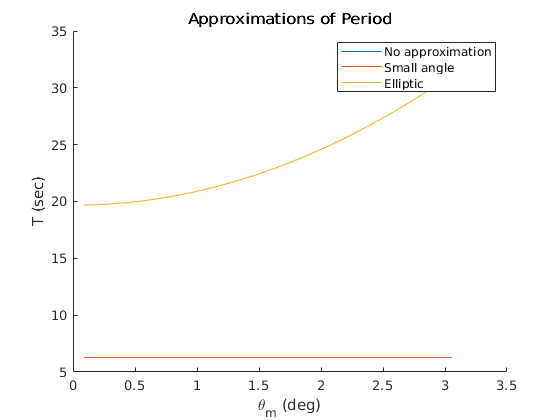

L = 9.8; % m
T_ellip = elli_period(L, thm);
% plot functions
figure(2)
hold on
    plot(thm, T_sin)
    plot(thm, T_small)
    plot(thm, T_ellip)
hold off
legend('No approximation', 'Small angle', 'Elliptic')
title("Approximations of Period")
xlabel("\theta_m (deg)")
ylabel("T (sec)")